clc;
h=0.1;
%{
p1 = input('value of a:');
p2 = input('value of b:');
p3 = input('value of c:');
--release this comment section to use--
%} 
t = 0:h:70;                                         
x = zeros(1,length(t)); 
y = zeros(1,length(t)); 
z = zeros(1,length(t)); 
x(1) = 1; y(1) = 1; z(1) = 1;
a=x(1); b=x(1);
    c=y(1); d=y(1);
    e=z(1); f=z(1);
F1_txyz = @(t,x,y,z) -y-z;
F2_txyz = @(t,x,y,z) x+0.2*y; %please use the input a=p1 here
F3_txyz = @(t,x,y,z) 0.2+z*(x-5.7); %please use the input b=p2 and c=p3 here
for i=1:(length(t)-1)
    k_1 = F1_txyz(t(i),x(i),y(i),z(i));
    l_1 = F2_txyz(t(i),a,c,e);
    m_1 = F3_txyz(t(i),b,d,f);
    k_2 = F1_txyz((t(i)+0.5*h),(x(i)+0.5*k_1*h),(y(i)+0.5*l_1*h),(z(i)+0.5*m_1*h));
    l_2 = F2_txyz((t(i)+0.5*h),(a+0.5*k_1*h),(c+0.5*l_1*h),(e+0.5*m_1*h));
    m_2 = F3_txyz((t(i)+0.5*h),(b+0.5*k_1*h),(d+0.5*l_1*h),(f+0.5*m_1*h));
    k_3 = F1_txyz((t(i)+0.5*h),(x(i)+0.5*k_2*h),(y(i)+0.5*l_2*h),(z(i)+0.5*m_2*h));
    l_3 = F2_txyz((t(i)+0.5*h),(a+0.5*k_2*h),(c+0.5*l_2*h),(e+0.5*m_2*h));
    m_3 = F3_txyz((t(i)+0.5*h),(b+0.5*k_2*h),(d+0.5*l_2*h),(f+0.5*m_2*h));
    k_4 = F1_txyz((t(i)+h),(x(i)+k_3*h),(y(i)+l_3*h),(z(i)+m_3*h));
    l_4 = F2_txyz((t(i)+h),(a+k_3*h),(c+l_3*h),(e+m_3*h));
    m_4 = F3_txyz((t(i)+h),(b+k_3*h),(d+m_3*h),(f+l_3*h));
    x(i+1) = x(i) + (1/6)*(k_1+2*k_2+2*k_3+k_4)*h;
    y(i+1) = y(i) + (1/6)*(l_1+2*l_2+2*l_3+l_4)*h;
    z(i+1) = z(i) + (1/6)*(m_1+2*m_2+2*m_3+m_4)*h;
    fprintf('iteration %d is : x = %f y = %f z = %f \n',i,x(i+1),y(i+1),z(i+1));
    a=x(i+1); b=x(i+1);
    c=y(i+1); d=y(i+1);
    e=z(i+1); f=z(i+1);
end

iteration 1 is : x = 0.813895 y = 1.111619 z = 0.595468 
iteration 2 is : x = 0.649976 y = 1.207927 z = 0.351178 
iteration 3 is : x = 0.496610 y = 1.290221 z = 0.207661 
iteration 4 is : x = 0.347049 y = 1.358915 z = 0.125509 
iteration 5 is : x = 0.197758 y = 1.413921 z = 0.079810 
iteration 6 is : x = 0.047239 y = 1.454900 z = 0.055322 
iteration 7 is : x = -0.104749 y = 1.481427 z = 0.042952 
iteration 8 is : x = -0.257680 y = 1.493082 z = 0.037395 
iteration 9 is : x = -0.410575 y = 1.489516 z = 0.035615 
iteration 10 is : x = -0.562185 y = 1.470487 z = 0.035905 
iteration 11 is : x = -0.711114 y = 1.435881 z = 0.037321 
iteration 12 is : x = -0.855887 y = 1.385728 z = 0.039342 
iteration 13 is : x = -0.995001 y = 1.320210 z = 0.041681 
iteration 14 is : x = -1.126957 y = 1.239663 z = 0.044170 
iteration 15 is : x = -1.250286 y = 1.144581 z = 0.046710 
iteration 16 is : x = -1.363569 y = 1.035614 z = 0.049230 
iteration 17 is : x = -1.465454 y = 0.913564 z = 0.051678 
iteration 18

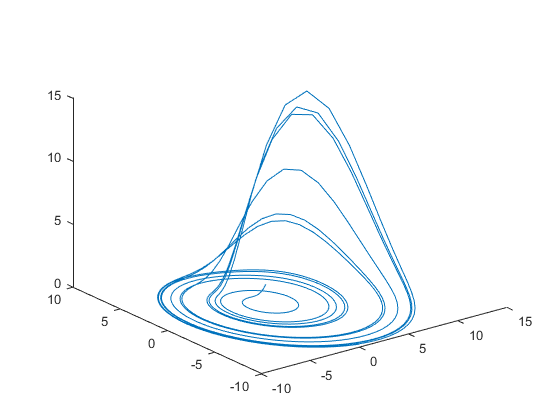

plot3(x,y,z)